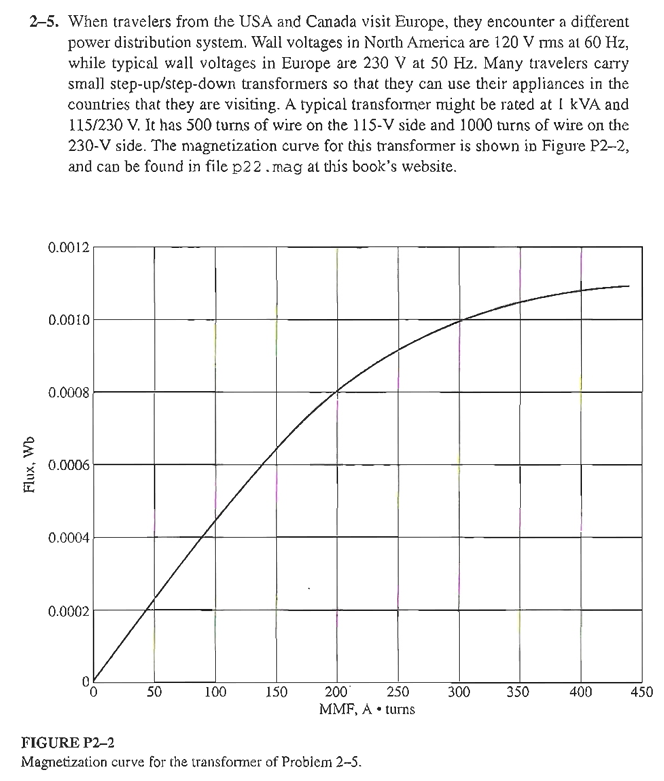

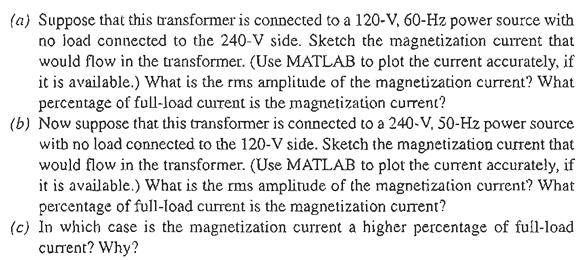

(a) Suppose that this transfonner is connected to a 120-V, 60-Hz power source with no load connected to the 240-V side. Sketch the magnetization current that would flow in the transformer. (Use MATLAB to plot the current accurately, if it is available.) What is the rms amplitude of the magnetization current? What percentage of full-load current is the magnetization current?

假設這個變壓器連接到一個 120 V、60 Hz 的電源，沒有負載連接到 240 V 側。繪製變壓器中流動的磁化電流。（如果可用，請使用 MATLAB 準確繪製電流。磁化電流的 rms 幅度是多少？磁化電流占滿載電流的百分比是多少？

load p22_mag.dat; 
mmf_data = p22_mag(:,1);
flux_data = p22_mag(:,2);

% Initialize values 
S = 1000;                   % Apparent power (VA) 
Vrms = 120;                 % Rms voltage (V) 
VM = Vrms * sqrt(2);        % Max voltage (V) 
NP = 500;                   % Primary turns

% Calculate angular velocity for 60 Hz 
freq = 60; % Freq (Hz) 
w = 2 * pi * freq; 

% Calculate flux versus time                   
time = 0:1/3000:1/30;       % 0 to 1/30 sec 
flux = -VM/(w*NP) * cos(w .* time); 
% Calculate the mmf corresponding to a given flux 
% using the MATLAB interpolation function. 
mmf = interp1(flux_data, mmf_data, flux); 
% Calculate the magnetization current 
im = mmf / NP; 

% Calculate the rms value of the current 
irms = sqrt(sum(im.^2)/length(im)); 
disp(['The rms current at 120 V and 60 Hz is ', num2str(irms)]); 

The rms current at 120 V and 60 Hz is 0.31863



% Calculate the full-load current 
i_full = S / Vrms; 
% Calculate the percentage of full-load current 
percnt = irms / i_full * 100; 
disp(['The magnetization current is ', num2str(percnt), '% of full-load current.']); 

The magnetization current is 3.8236% of full-load current.


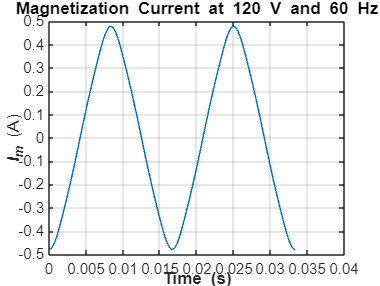

% Plot the magnetization current. 
figure(1) 
plot(time,im); 
title ('\bfMagnetization Current at 120 V and 60 Hz'); 
xlabel ('\bfTime (s)'); 
ylabel ('\bf\itI_{m} \rm(A)'); 
axis([0 0.04 -0.5 0.5]); 
grid on;

(b) Now suppose that this transfonner is connected to a 240-V, 50-Hz power source with no load connected to the 120-V side. Sketch the magnetization current that would flow in the transformer. (Use MATLAB to plot the current accurately, if it is available.) What is the rms amplitude of the magnetization current? What percentage of fuIl-load current is the magnetization current?

現在假設這個變壓器連接到一個 240 V、50 Hz 的電源，沒有負載連接到 120 V 側。繪製變壓器中流動的磁化電流。（如果可用，請使用 MATLAB 準確計算電流。磁化電流的 rms 幅度是多少？磁化電流占滿載電流的百分比是多少？

% Initialize values 
S = 1000;                   % Apparent power (VA) 
Vrms = 240;                 % Rms voltage (V) 
VM = Vrms * sqrt(2);        % Max voltage (V) 
NP = 1000;                  % Primary turns 
% Calculate angular velocity for 50 Hz 
freq = 50; % Freq (Hz) 
w = 2 * pi * freq; 
% Calculate flux versus time                
time = 0:1/2500:1/25;       % 0 to 1/25 sec 
flux = -VM/(w*NP) * cos(w .* time); 
% Calculate the mmf corresponding to a given flux 
% using the MATLAB interpolation function. 
mmf = interp1(flux_data,mmf_data,flux); 
% Calculate the magnetization current 
im = mmf / NP; 
% Calculate the rms value of the current 
irms = sqrt(sum(im.^2)/length(im)); 
disp(['The rms current at 50 Hz is ', num2str(irms)]); 

The rms current at 50 Hz is 0.22973


% Calculate the full-load current 
i_full = S / Vrms; 
% Calculate the percentage of full-load current 
percnt = irms / i_full * 100; 
disp(['The magnetization current is ', num2str(percnt), '% of full-load current.']); 

The magnetization current is 5.5134% of full-load current.


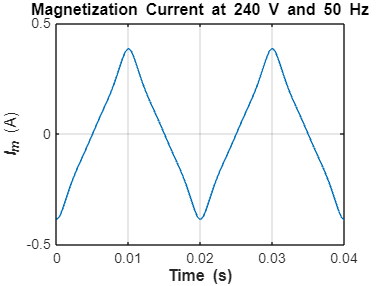

% Plot the magnetization current. 
figure(1); 
plot(time,im); 
title ('\bfMagnetization Current at 240 V and 50 Hz'); 
xlabel ('\bfTime (s)'); 
ylabel ('\bf\itI_{m} \rm(A)'); 
axis([0 0.04 -0.5 0.5]); 
grid on;

(c) In which case is the magnetization current a higher percentage of full-load current? Why?

% The magnetization current is a higher percentage of the full-load current for the 50 Hz case than for the 60 Hz case.  This is true because the peak flux is higher for the 50 Hz waveform, driving the core further into saturation.
% 磁化電流在50Hz情況下佔滿載電流的比例比在60Hz情況下更高。這是因為50Hz波形的峰值磁通量較高，使變壓器鐵芯更接近飽和。

hw

假設這個變壓器連接到一個 120 V、60 Hz 的電源，沒有負載連接到 240 V 側。繪製變壓器中流動的磁化電流。（如果可用，請使用 MATLAB 準確繪製電流。磁化電流的 rms 幅度是多少？磁化電流占滿載電流的百分比是多少？

load p22_mag.dat; 
mmf_data = p22_mag(:,1);  % 讀取 mmf (磁動勢) 數據
flux_data = p22_mag(:,2);  % 讀取 flux (磁通) 數據

% 參數
S = 1000;                   % 顯性功率 (VA)
Vrms = 120;                 % 有效電壓 (V)
VM = Vrms * sqrt(2);        % 最大電壓 (V)
NP = 500;                   % 初級繞組匝數

% 計算 60 Hz 的角速度
freq = 60; % 頻率 (Hz)
w = 2 * pi * freq;

% 計算隨時間變化的磁通
time = 0 : 1/3000 : 1/30;       % 時間從 0 到 1/30 秒
flux = -VM/(w*NP) * cos(w .* time); 

% 計算對應於給定磁通的 mmf
% 使用 MATLAB 的插值函數。
mmf = interp1(flux_data, mmf_data, flux); 

% 計算磁化電流
im = mmf / NP; 

% 計算電流的 rms 值
irms = sqrt(sum(im.^2)/length(im)); 
disp('(a)'); 
disp(['在 120 V 和 60 Hz 下的 rms 電流為 ', num2str(irms)]); 

在 120 V 和 60 Hz 下的 rms 電流為 0.31863



% 計算滿載電流
i_full = S / Vrms; 
% 計算滿載電流的百分比
percnt = irms / i_full * 100; 
disp(['磁化電流佔滿載電流的 ', num2str(percnt), '%。']); 

磁化電流是滿載電流的 3.8236%。


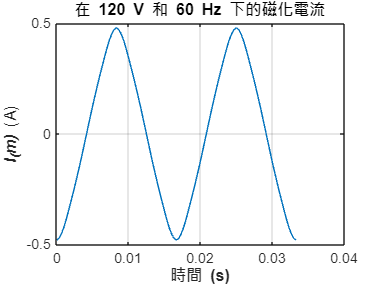


% 繪製磁化電流
figure(1) 
plot(time, im); 
title ('\bf在 120 V 和 60 Hz 下的磁化電流'); 
xlabel ('\bf時間 (s)'); 
ylabel ('\bf\itI_(m) \rm(A)'); 
axis([0 0.04 -0.5 0.5]); 
grid on;

(b) 現在假設這個變壓器連接到 240 V，50 Hz 的電源，沒有負載連接到 120 V 側繪製在變壓器中流動的磁化電流（如果可用，請使用 MATLAB 準確計算電流。） 

磁化電流的 rms 幅度是多少？ 

磁化電流占滿載電流的百分比是多少？

% 參數 
S = 1000;                   % 顯性功率 (VA) 
Vrms = 240;                 % 有效電壓 (V) 
VM = Vrms * sqrt(2);        % 最大電壓 (V) 
NP = 1000;                  % 初級繞組匝數 

% 計算 50 Hz 的角速度
freq = 50; % 頻率 (Hz) 
w = 2 * pi * freq;

% 計算隨時間變化的磁通                
time = 0 : 1/2500 : 1/25;       % 時間從 0 到 1/25 秒 
flux = -VM/(w * NP) * cos(w .* time); 

% 計算對應於給定磁通的 mmf
% 使用 MATLAB 的插值函數。
mmf = interp1(flux_data, mmf_data, flux); 

% 計算磁化電流 
im = mmf / NP; 

% 計算電流的 rms 值 
irms = sqrt(sum(im .^ 2) / length(im)); 
disp(['在 50 Hz 下的 rms 電流為 ', num2str(irms)]); 

在 50 Hz 下的 rms 電流為 0.22973



% 計算滿載電流 
i_full = S / Vrms; 

% 計算滿載電流的百分比 
percnt = irms / i_full * 100; 
disp(['磁化電流佔滿載電流的 ', num2str(percnt), '%。']); 

磁化電流是滿載電流的 5.5134%。


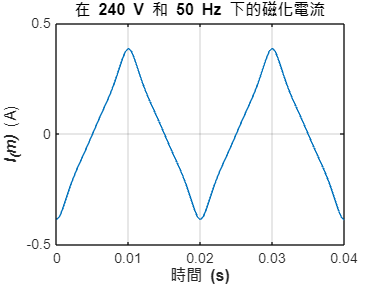


% 繪製磁化電流 
figure(1); 
plot(time, im); 
title ('\bf在 240 V 和 50 Hz 下的磁化電流'); 
xlabel ('\bf時間 (s)'); 
ylabel ('\bf\itI_(m) \rm(A)'); 
axis([0 0.04 -0.5 0.5]); 
grid on;

(c) In which case is the magnetization current a higher percentage of full-load current? Why?

disp('在240V、50Hz的情況下，磁化電流占滿載電流的百分比較高。'); 

在240V、50Hz的情況下，磁化電流占滿載電流的百分比較高。


disp('因為頻率降低後，為了維持相同的磁通量需要更大的磁化電流，磁化電流增加後，相對於滿載電流的百分比也就提高了，所以在 240V、50Hz 下，磁化電流占滿載電流的比例較高。'); 

因為頻率降低後，為了維持相同的磁通量需要更大的磁化電流，磁化電流增加後，相對於滿載電流的百分比也就提高了，所以在 240V、50Hz 下，磁化電流占滿載電流的比例較高。
